# Inverse Kinematics of Stewart Platform (Hexapod)

## Input

% Desired position [x, y, z] in mm
desired_position = [1.03976319515219;   0.421489098064578;  179.841881621400]; 
% Desired orientation [roll, pitch, yaw] in radians
desired_orientation = [0.00138056756004534;    0.00207693768229920;   -0.0311047657694660]; 					

## Data


R1=130/2; % radius of the Fixed Platform
R2=125/2; % radius of the Moving Platform
GAMMA=20; % half angle between to adjacent legs


% Define the fixed and moving platform geometry

        % % Theoretical Fixed platform leg points
        % B1=[R1*cosd(60-GAMMA) R1*sind(60-GAMMA) 0]'; 
        % B2=[R1*cosd(60+GAMMA) R1*sind(60+GAMMA) 0]'; 
        % B3=[-R1*cosd(GAMMA) R1*sind(GAMMA) 0]'; 
        % B4=[-R1*cosd(GAMMA) -R1*sind(GAMMA) 0]'; 
        % B5=[R1*cosd(60+GAMMA) -R1*sind(60+GAMMA) 0]'; 
        % B6=[R1*cosd(60-GAMMA) -R1*sind(60-GAMMA) 0]'; 

        % B = [B1 B2 B3 B4 B5 B6];

% Actual Fixed platform legs points
B1=[49.834,41.765,-10.52+11]'; 
B2=[11.327,63.988,-10.504+11]'; 
B3=[-61.058, 22.228,-10.654+11]'; 
B4=[-61.06,-22.233,-10.803+11]'; 
B5=[11.3,-64.009,-10.898+11]'; 
B6=[49.825,-41.784,-10.779+11]'; 

B = [B1 B2 B3 B4 B5 B6];

        % % Theoretical Moving platform legs points
        % P1=[R2*cosd(GAMMA) R2*sind(GAMMA) 0]';
        % P2=[-R2*sind(30-GAMMA) R2*cosd(30-GAMMA) 0]';
        % P3=[-R2*sind(30+GAMMA) R2*cosd(30+GAMMA) 0]';
        % P4=[-R2*sind(30+GAMMA) -R2*cosd(30+GAMMA) 0]';
        % P5=[-R2*sind(30-GAMMA) -R2*cosd(30-GAMMA) 0]';
        % P6=[R2*cosd(GAMMA) -R2*sind(GAMMA) 0]';
     
        % P = [P1 P2 P3 P4 P5 P6];

% Actual Moving platform legs points
P1=[58.708,21.383,-11.171+11]';
P2=[-10.875,61.556,-10.94+11]';
P3=[-47.912,40.187,-10.888+11]';
P4=[-47.907,-40.162,-11.017+11]';
P5=[-10.873,-61.536,-11.135+11]';
P6=[58.704,-21.364,-11.243+11]';

P = [P1 P2 P3 P4 P5 P6];

## Output

% Solve inverse kinematics to find the lengths
leg_lengths = inverseKinematics(desired_position, desired_orientation, B, P);

Leg Lengths are (mm):
	1. 180.724260 
	2. 180.546310 
	3. 181.514478 
	4. 180.852855 
	5. 181.048878 
	6. 180.468455 


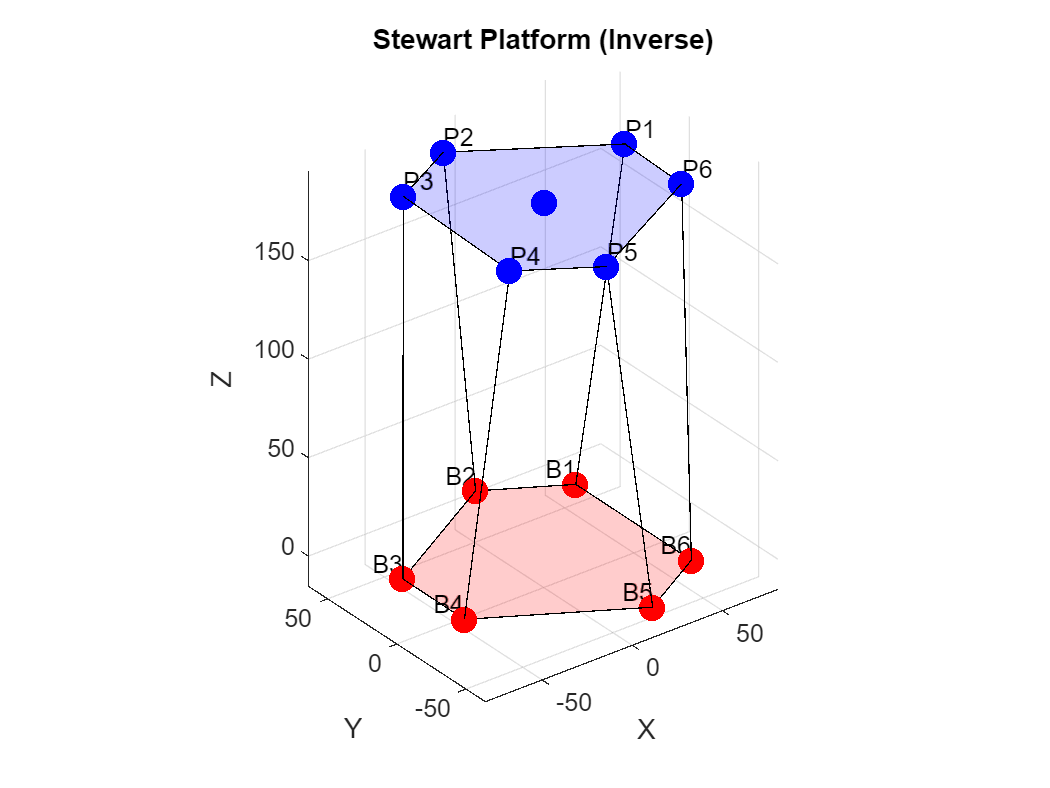

% Display the Stewart platform
[R, P_global, top_centre] = displayStewartPlatform(desired_position, desired_orientation, B, P);

## Functions

### Function to Calculate Leg Lengths

function leg_lengths = inverseKinematics(desired_position, desired_orientation, B, P)
    % Convert Euler angles to rotation matrix
    R = Eul2rotm(desired_orientation);

    % Calculate leg lengths
    leg_lengths = zeros(6, 1);
    disp("Leg Lengths are (mm):")
    for i = 1:6
        % Position of attachment point on moving platform in world frame
        Pi = desired_position + R * P(:, i);
       
       
        % Vector from base attachment point to moving platform attachment point
        L = Pi - B(:, i);
      
        % Leg length
        leg_lengths(i) = norm(L);
        
        fprintf("\t%i. %f \n",i,leg_lengths(i))
    end

end

### Function to create Rotational Matrix from Euler angles


% function to convert Euler angles to rotation matrix

function R = Eul2rotm(eul)
    % Euler angles are in the order of [roll, pitch, yaw]
    R = eul2rotm([eul(1), eul(2), eul(3)],"XYZ");
end


### Function to Plot

function [R, P_global, top_centre] = displayStewartPlatform(desired_position, desired_orientation, B, P)
    % Convert orientation to rotation matrix
    R = Eul2rotm(desired_orientation);
    P_global = desired_position + R * P;

    % Plot the base attachment points
    figure;
    hold on;
    plot3(B(1,:), B(2,:), B(3,:), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    hold on
    fill3(B(1,:), B(2,:), B(3,:),'r', 'FaceAlpha', 0.2);
    text(B(1,:), B(2,:), B(3,:), {'B1', 'B2', 'B3', 'B4', 'B5', 'B6'},'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

    % Plot the platform attachment points
    plot3(P_global(1,:), P_global(2,:), P_global(3,:), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    hold on
    fill3(P_global(1,:), P_global(2,:), P_global(3,:),'b','FaceAlpha', 0.2);
    text(P_global(1,:), P_global(2,:), P_global(3,:), {'P1', 'P2', 'P3', 'P4', 'P5', 'P6'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

    % Plot the legs
    for i = 1:6
        plot3([B(1,i), P_global(1,i)], [B(2,i), P_global(2,i)], [B(3,i), P_global(3,i)], 'k-');
    end

    % Plot Centre
    top_centre = mean(P_global,2);
    plot3(top_centre(1),top_centre(2),top_centre(3),'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    
    % Plot settings
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Stewart Platform (Inverse)');
    grid on;
    axis equal;
    view(3);
    hold off;
end

## Reference Diagram